format shortg
clear all

# Oppgave 2

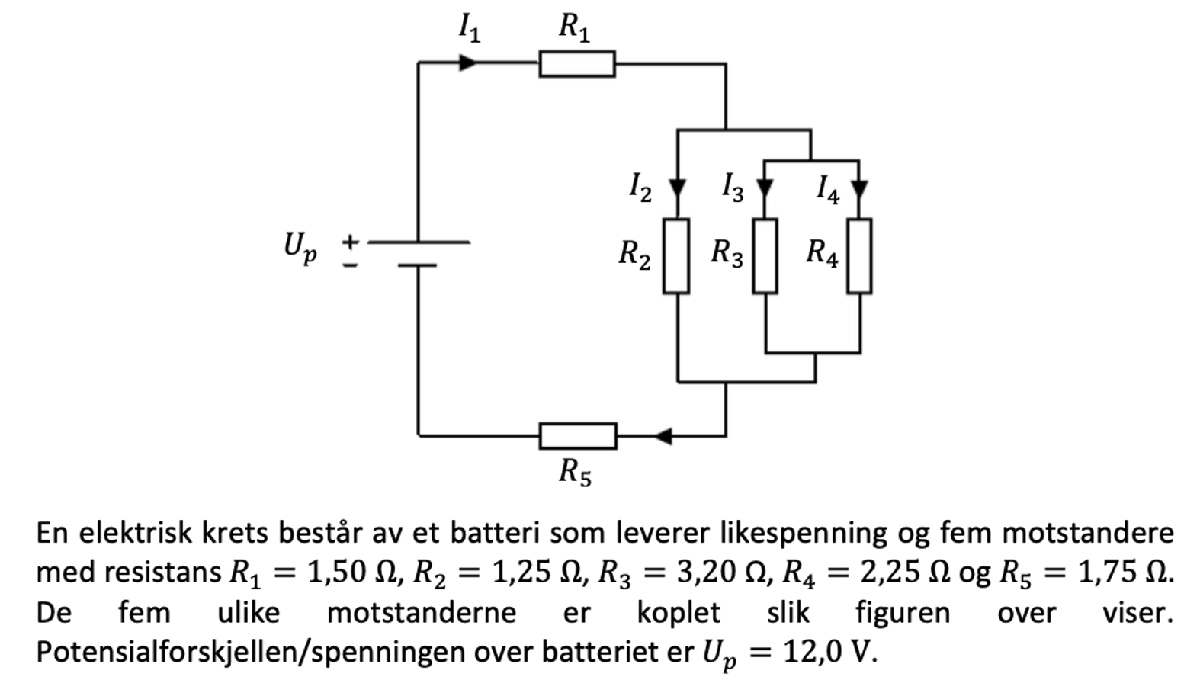

R_1 = 1.50; % Ohm
R_2 = 1.25; % Ohm
R_3 = 3.20; % Ohm
R_4 = 2.25; % Ohm
R_5 = 1.75; % Ohm
U_p = 12.0; % Volt

Vi har to regler å forholde oss til når det kommer til motstander, nemlig om de er koblet i serie eller i parallel. Vi ønsker så å finne den effektive resistansen i samlingen av motstander og begynner derfor med ${R_2 ,\;R}_3 \;\textrm{og}\;R_4$som er paralellkooblet:

I parallell er total motstand: $\frac{1}{R_{\textrm{eff}} }=\frac{1}{R_1 }+\frac{1}{R_2 }\ldotp \ldotp \ldotp +\frac{1}{R_n }$ da får vi for parallelkoblingen $R_{234}$:


$$\frac{1}{R_{34} }=\frac{1}{R_2 }+\frac{1}{R_3 }+\frac{1}{R_4 }\Rightarrow R_{34} =\frac{1}{1/R_2 +1/R_3 +1/R_4 }$$


R_234 = 1/((1/R_2)+(1/R_3)+(1/R_4))

R_234 =       0.64228


R_234 = R_par([R_2 R_3 R_4])

R_234 =       0.64228


Denne paralellkoblingen er koblet i serie med $R_1$ og $R_5$ hvor den totale motstanden er gitt ved:


$$R_{\textrm{eff}} =R_1 +R_2 \ldotp \ldotp \ldotp \ldotp +R_n$$


R_eff = R_1 + R_234 + R_5;
R_eff = R_ser([R_1 R_par([R_2 R_3 R_4]) R_5])

R_eff =        3.8923


fprintf('R_eff = %g Ohm', signif(R_eff, 3))

R_eff = 3.89 Ohm

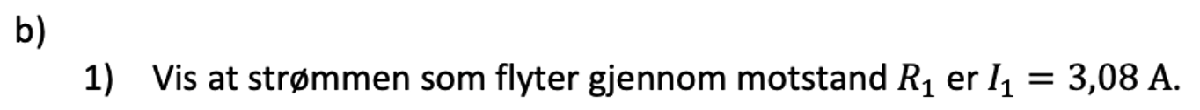

Strømmen gjennom motstand $R_1$ finner vi med Ohms lov: $I=\frac{U}{R}$

I_1 = U_p/R_eff;
I_1 = ohms_lov(U_p, R_eff, 0);
fprintf('Strømmen gjennom R_1 er : %g A', signif(I_1, 3))

Strømmen gjennom R_1 er : 3.08 A

Strømmen gjennom $R_5$ er lik $I_1$ kan forklares med Korchoffs lover:

Mer spesifikt sier kirchoffs forgreiningslov at strømmen inn og ut av en forgreining skal være den samme, dette betyr blant annert at strømmen som går inn i batteriet fra $R_5$ må være like stor som strømmen som går ut av batteriet og dermed like stor som $I_1$ Vi kan også se på på parallellkoblingene at siden hver forgreining vil ha samme strøm inn og ut vil strømmen fra $I_1$ dele seg opp i parallellkoblingene, for å å slå seg sammen igjen når parallelkoblingen er slutt, dermed vil $I_{R_5 } =I_1$


$$I_1 =I_2 +I_3 +I_4 =I_5$$


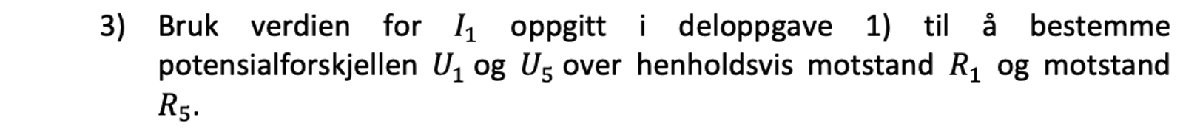

Bruker Ohms lov over motsandene: da får vi:

U_1 = R_1 * I_1;
U_5 = R_5 * I_1;
fprintf('U_1 = %g Volt\nU_5 = %g Volt', signif(U_1, 3), signif(U_5, 3))

U_1 = 4.62 Volt
U_5 = 5.4 Volt

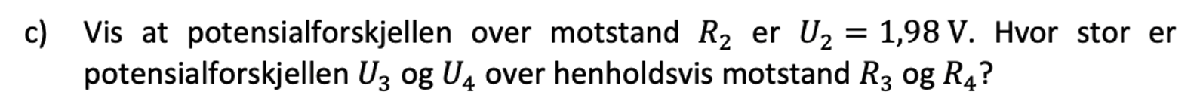

Vi vet at i paralellkoblinger er potenislaforskjellen mellom grenene lik, dette betyr at $U_2 =U_3 =U_4 =U_{234}$ siden disse tre er koblet i parallell. Vi vet også Potensialforskjellen over batteriet, $R_1 \;\textrm{og}\;R_5$og potensialforskjellen kan skrives som:


$$U_p =U_1 +U_{234} +U_5 \Rightarrow U_{234} =U_p -U_1 -U_5$$


U_234 = U_p - U_1 - U_5;
fprintf('Potensialforskjellen over alle motstandene R2, R3 og R4 er: %g Volt', signif(U_234, 3))

Potensialforskjellen over alle motstandene R2, R3 og R4 er: 1.98 Volt

Bruker Ohms lov: $I=\frac{U}{R}$

I_2 = U_234/R_2;
I_3 = U_234/R_3;
I_4 = U_234/R_4;
fprintf('I_2 = %g Ampere\nI_3 = %g Ampere\nI_4 = %g Ampere', signif(I_2, 3), signif(I_3, 3), signif(I_4, 3))

I_2 = 1.58 Ampere
I_3 = 0.619 Ampere
I_4 = 0.88 Ampere

R_i = 0.750; % Ohm

Batteriet skal opprettholde en strøm på: $I_1 =3\ldotp 08\;A$

e = 2

e =      2
